x = [10 20 30 40 50 60 70 80 90 100]

x =     10    20    30    40    50    60    70    80    90   100


VRt = [2093 1378 0884 0583 0404 0280 0200 0144 0106 0079]

VRt =         2093        1378         884         583         404         280         200         144         106          79


vr = repmat(0.9974, 1, 10);
y = VRt./ vr

y = 1.0e+03 *

    2.0985    1.3816    0.8863    0.5845    0.4051    0.2807    0.2005    0.1444    0.1063    0.0792




model = @(params, x) params(1) * exp(-params(2) * x);

% 初始化拟合参数
initialGuess = [1, 0.1];

% 进行非线性拟合
params = lsqcurvefit(model, initialGuess, x, y);


可能存在局部最小值。

lsqcurvefit 已停止，因为平方和相对于其初始值的最终变化小于函数容差值。

<停止条件详细信息>


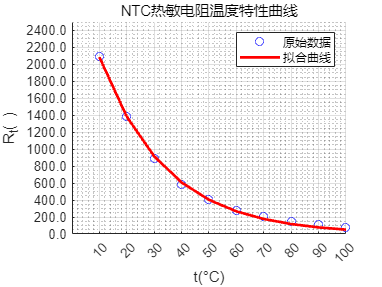


% 生成拟合的曲线
fit_curve = model(params, x);

% 绘制原始数据和拟合曲线
figure;
scatter(x, y, 'b');  % 散点图
hold on;
plot(x, fit_curve, 'r', 'LineWidth', 2);  % 拟合曲线
xlabel('t(\circC)')
xticks(10:10:100)
yticks(0.0:200.0:2500.0)
ylabel('R_{t}( )')
ytickformat('%.1f');
legend('原始数据', '拟合曲线');
title('NTC热敏电阻温度特性曲线');
hold off;

grid on
grid minor